# Lecture 6: Spatial Filtering

# Part 3: Order Statistics (Non-linear) Filters

Author: Dr. Zeynep Cipiloglu Yildiz

Notes:

- Sample images are available in the images folder of the current directory. (You may need to add images folder into your path.)

- Related lecture: Lecture6 - Spatial Filtering

- pdf versions of the .mlx files are also available for those using GNU Octave

% clear workspace variables and close windows
clc, clearvars, close all;

% read image
I = imread('images/cameraman_noisy.tif');

## Median Filter

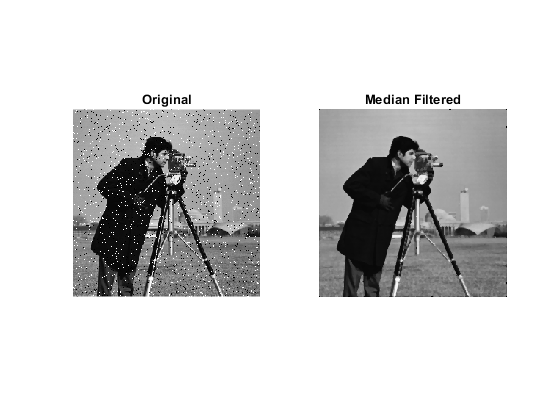

I1 = medfilt2(I);
figure, subplot(1,2,1), imshow(I), title('Original');
subplot(1,2,2), imshow(I1), title('Median Filtered');

## Min/Max Filter

*Note:** You can also use nlfilter as shown below*

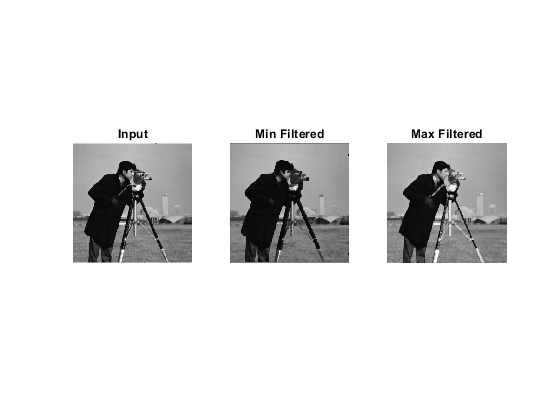

Imin = ordfilt2(I1,1,true(3));
Imax = ordfilt2(I1,9,true(3));

figure, subplot(1,3,1), imshow(I1), title('Input');
subplot(1,3,2), imshow(Imin), title('Min Filtered');
subplot(1,3,3), imshow(Imax), title('Max Filtered');

## **Custom Nonlinear Filtering**

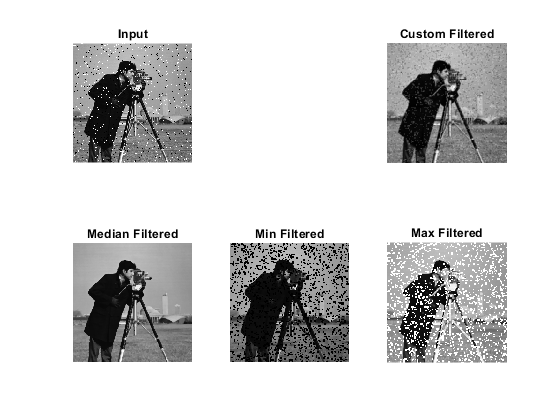

fun1 = @(x) median(x(:)); % median filter
I2 = nlfilter(I,[3 3],fun1); 

fun2 = @(x) min(x(:)); % min filter
I3 = nlfilter(I,[3 3],fun2); 

fun3 = @(x) max(x(:)); % max filter
I4 = nlfilter(I,[3 3],fun3); 

fun4 = @(x) 2*mean(x(:))-100; % a custom filter
I5 = nlfilter(I,[3 3],fun4); 

figure, subplot(2,3,1), imshow(I), title('Input');
subplot(2,3,4), imshow(I2), title('Median Filtered');
subplot(2,3,5), imshow(I3), title('Min Filtered');
subplot(2,3,6), imshow(I4), title('Max Filtered');
subplot(2,3,3), imshow(I5,[]), title('Custom Filtered');